clear all; close all;
global  parFAULT parRUP parEQ ;

## Model parameters

Parameters defining fault extent and seismicity distribution

% Model parameters - Fault 
parFAULT.L      = 200000;
parFAULT.W      = 30000;
parFAULT.res    = 500;
% Distribution of seismicity along fault width
parFAULT.dist   = 'Normal'; % or 'Uniform'
parFAULT.mu     = parFAULT.W/2; % peak of seismicity
parFAULT.sigma  = parFAULT.W/5; % distribution half-width
parFAULT.chi=0.5; % fraction of seismic slip over total fault slip
% Compute the ratio between the Gaussian distribution and the normal
% distribution - parFAULT.ratio is the peak to peak ratio
if (strcmp(parFAULT.dist,'Normal'))
    pd = makedist('Normal','mu',parFAULT.mu,'sigma',parFAULT.sigma);pdN = truncate(pd,0,parFAULT.W);
    parFAULT.ratio=pdf(pdN, parFAULT.mu)./unifpdf(parFAULT.mu,0,parFAULT.W);
else
    parFAULT.ratio=1;
end

Parameters defining ruptures and the used scaling laws

% Model parameters - Earthquake rupture [Leonard, 2010]
% Reverse fault
parRUP.mu       = 30e9;                            % Shear modulus (Pa)
parRUP.Beta     = 2/3;                             % parameter Leonard or Beta=1
parRUP.C1       = 17.5;                            % parameter Leonard
parRUP.C2       = 3.8e-5;                          % parameter Leonard
% Define maximum and minimum earthquake magnitude
parRUP.Lmax     = parFAULT.L;
parRUP.Wmax     = parFAULT.W;
parRUP.MoLmax   = parRUP.mu*parRUP.C1^(3/2)*parRUP.C2*parFAULT.L.^(3/2*(1+parRUP.Beta));
parRUP.MoWmax   = parRUP.mu*parRUP.C1^(-3/(2*parRUP.Beta))*parRUP.C2*parFAULT.W.^(3/2*(1+1/parRUP.Beta));
parRUP.Momax    = min(parRUP.MoLmax,parRUP.MoWmax);
parRUP.Mwmax    = 2/3*log10(parRUP.Momax)-6.07;
parRUP.Lmin     = parFAULT.res;
parRUP.Wmin     = parFAULT.res;
parRUP.MoLmin   = parRUP.mu*parRUP.C1^(3/2)*parRUP.C2*parRUP.Lmin.^(3/2*(1+parRUP.Beta));
parRUP.MoWmin   = parRUP.mu*parRUP.C1^(-3/(2*parRUP.Beta))*parRUP.C2*parRUP.Wmin.^(3/2*(1+1/parRUP.Beta));
parRUP.Momin    = max(parRUP.MoLmin,parRUP.MoWmin);
parRUP.Mwmin    = 2/3*log10(parRUP.Momin)-6.07;

Parametersused in the earthquake generator model

% Model parameters - EarthQuake generator [Turcotte et al., 2007]
parEQ.type      = 'Gutenberg-Richter';
parEQ.T         = 2e3.*365;                                                % Total time duration (days)
parEQ.mw_min    = parRUP.Mwmin;                                            % Minimum Magnitude (deterministic)
parEQ.mw_max    = parRUP.Mwmax;                                            % Maximum Magnitude (deterministic)
parEQ.mw_dm     = 0.02;                                                    % Magnitude steps
parEQ.mw        = parEQ.mw_min:parEQ.mw_dm:parEQ.mw_max;
parEQ.b         = 1;                                                       % GR param for Mainshocks and Aftershocks
parEQ.Dm        = 1.25;                                                    % GR-Bath param
parEQ.c         = 0.1;                                                     % temporal Omori param
parEQ.p         = 1.25;                                                    % temporal Omori param
parEQ.d         = 4.0;                                                     % spatial Omori param
parEQ.q         = 1.35;                                                    % spatial Omori param
if (strcmp(parEQ.type,'Periodic'))
    parEQ.period    = 330*365;                                                 % Periodicity of the Main shocks
    parEQ.Mwevent   = 8;                                                       % Magnitude of the reccurent event
    parEQ.Nmain     = floor(parEQ.T./parEQ.period)+1;                          % Number of mainshocks
elseif (strcmp(parEQ.type,'Gutenberg-Richter'))
    parEQ.srate     = 0.1./parFAULT.ratio;                                     % Number of mainshock per day
    parEQ.Nmain     = parEQ.T*parEQ.srate;                                     % Number of mainshocks
    parEQ.a         = log10(parEQ.T.*parEQ.srate) + parEQ.b*parEQ.mw_min;      % GR param for Mainshocks - for Mw>=Mwmin
end


## Mainshocks and Aftershocks

Compute a distribution of mainshocks ("Mainshock") following the Gutenberg-Richter and the associated aftershocks ("Aftershock") using the BASS model (Turcotte et al., 2007). The variable "Earthquake" is a concatenation of "Mainshock" and "Aftershock".

% Mainshocks
Mainshock  = fMainshock();

% Aftershocks
tic
Aftershock(1,numel(Mainshock)).Mw=[];Aftershock(1,numel(Mainshock)).x=[];Aftershock(1,numel(Mainshock)).y=[];Aftershock(1,numel(Mainshock)).z=[];Aftershock(1,numel(Mainshock)).g=[];Aftershock(1,numel(Mainshock)).t=[];Aftershock(1,numel(Mainshock)).dt=[];
for i = 1:length(Mainshock.Mw)
    Aftershock(i) = fBASS_local(Mainshock.Mw(i),Mainshock.x(i),Mainshock.y(i),Mainshock.z(i),Mainshock.g(i),Mainshock.t(i),Mainshock.dt(i));
end
toc

Elapsed time is 33.289461 seconds.



% All earthquakes
Earthquake = fEarthquake(Mainshock,Aftershock);

Earthquake frequency-magnitude computed ...


## Earthquake Rupture & fault slip

Compute for each earthquake the rupture extent and displacement using Leonard (2010) scaling laws. 

% Compute ruptures
[Earthquake] = fRupture(Earthquake);

% Compute slip along the fault
[Slip]=fSlip(Earthquake);

% Some properties
V=sum(Earthquake.Mo)/(parEQ.T*parFAULT.W*parFAULT.L*parRUP.mu).*1000*365; % Fault average slip (mm/yr)
C=parEQ.T./(365*1000);

Identify earthquakes rupturing the surface ("EQsur") or the river ("EQriv").

% Keep only Earthquakes that ruptured the surface
ind = Slip.indsur;
EQsur.t  = Earthquake.t(ind);    EQsur.Mw = Earthquake.Mw(ind);    EQsur.Mo = Earthquake.Mo(ind);    EQsur.x  = Earthquake.x(ind);    EQsur.y  = Earthquake.y(ind);    EQsur.W  = Earthquake.W(ind);    EQsur.L  = Earthquake.L(ind);    EQsur.D  = Earthquake.D(ind);

% Keep only Earthquakes that ruptured the surface at the location of the river
ind = Slip.indriv;
EQriv.t  = Earthquake.t(ind);    EQriv.Mw = Earthquake.Mw(ind);    EQriv.Mo = Earthquake.Mo(ind);    EQriv.x  = Earthquake.x(ind);    EQriv.y  = Earthquake.y(ind);    EQriv.W  = Earthquake.W(ind);    EQriv.L  = Earthquake.L(ind);    EQriv.D  = Earthquake.D(ind);

## Figures - model general

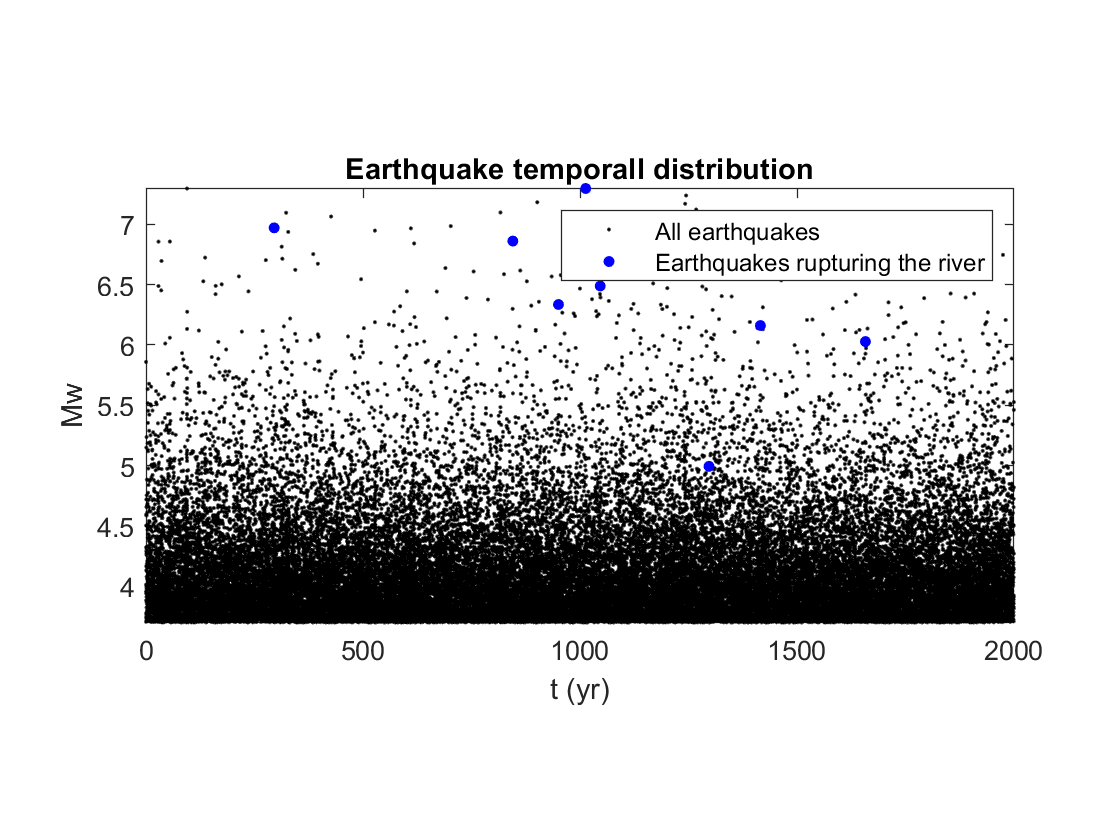

% Temporal distribution of earthquakes
figure();
plot(Earthquake.t./365,Earthquake.Mw,'.k','MarkerSize',4);hold on;plot(EQriv.t./365,EQriv.Mw,'.b','MarkerSize',14);xlabel('t (yr)');ylabel('Mw');axis tight;xlim([0 parEQ.T./365]);
legend('All earthquakes','Earthquakes rupturing the river');pbaspect([5 2.5 1])
title('Earthquake temporall distribution')

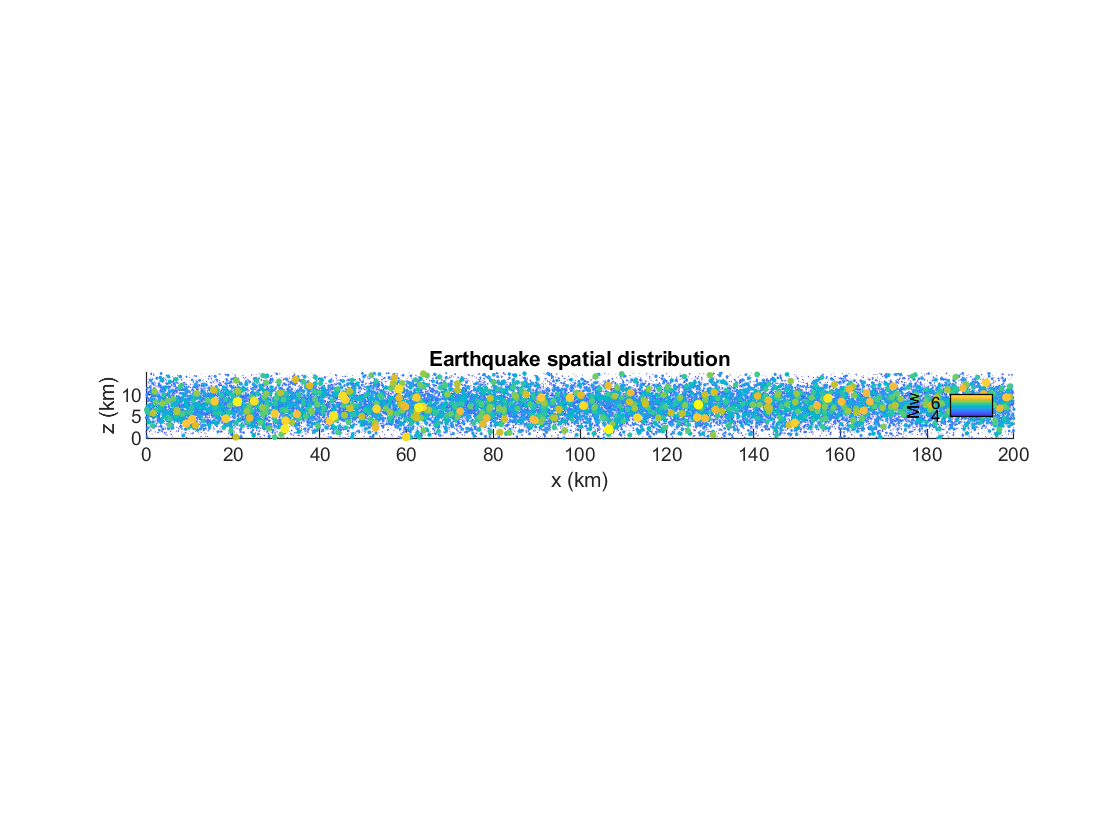


% Map of earthquakes
figure();
[~,ind]=sort(Earthquake.Mw,'ascend');scatter(Earthquake.y(ind)./1000,Earthquake.x(ind).*sind(30)./1000,(1.*(Earthquake.Mw(ind)-parRUP.Mwmin+0.1)).^2,Earthquake.Mw(ind),'fill'); axis equal tight;xlabel('x (km)');ylabel('z (km)');xlim([0 parFAULT.L]./1000);ylim([0 parFAULT.W*sind(30)]./1000);
set(gca,'fontsize',7);c = colorbar('east'); ax = gca; axpos = ax.Position; c.Label.String = 'Mw'; c.Color='k'; 
title('Earthquake spatial distribution')

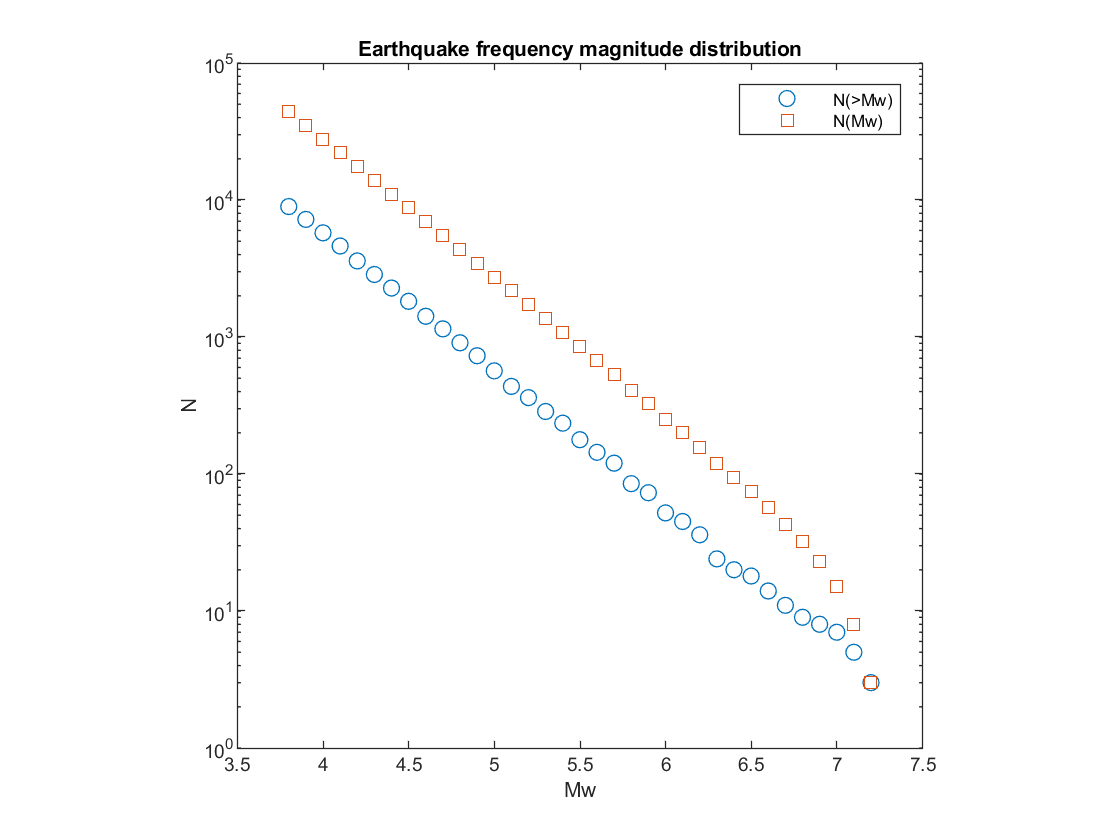


% Frequency-magnitude distribution
figure();
dml=0.1;ml=min(Earthquake.Mw)-1e-32:dml:max(Earthquake.Mw)+1e-32;ml_save=ml;n=histc(Earthquake.Mw,ml);n(n==0)=NaN;dml=diff(ml);ml(end)=[];n(end)=[];ml=ml+dml;
ncum=cumsum(n,'reverse');
semilogy(ml,n,'o',ml,ncum,'s');xlabel('Mw');ylabel('N');pbaspect([1 1 1]);legend('N(>Mw)','N(Mw)');
set(gca,'fontsize',7);
title('Earthquake frequency magnitude distribution');

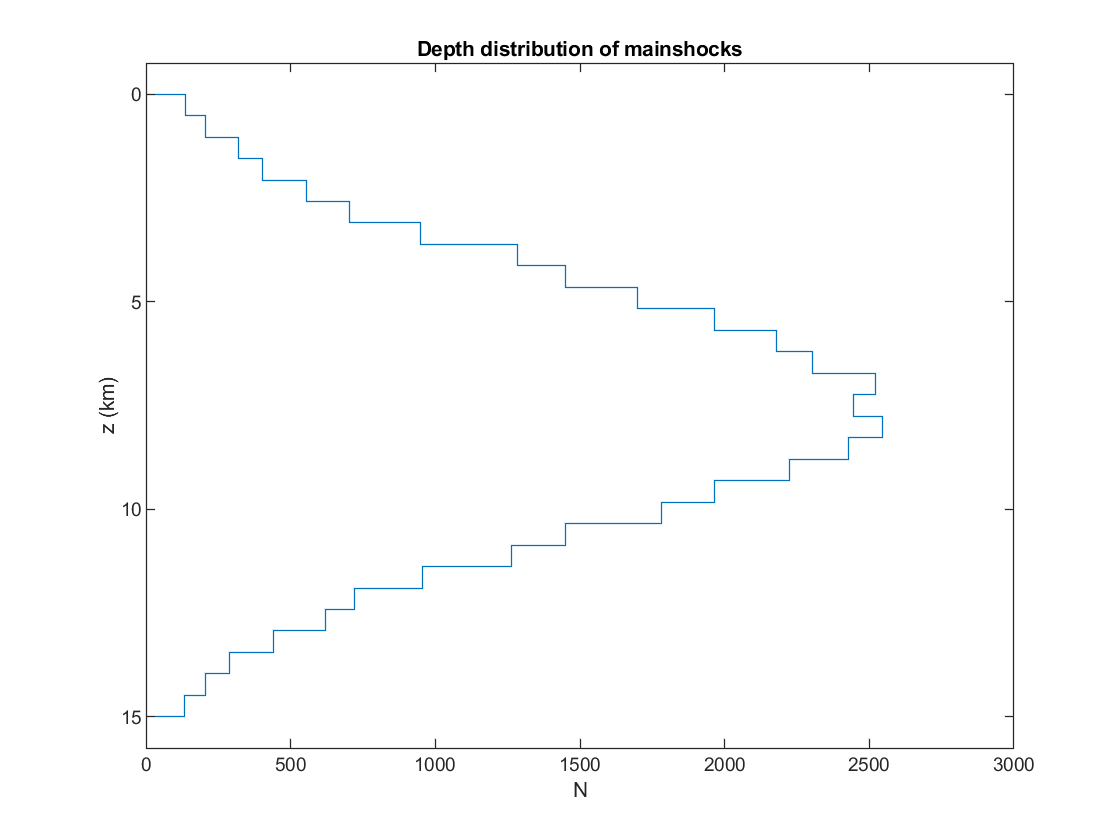


% Mainshock depth distribution
figure();
histogram(Mainshock.x.*sind(30)./1000,linspace(0,parFAULT.W,30).*sind(30)./1000,'DisplayStyle','Stairs');
view(90, 90);xlabel('z (km)');ylabel('N');
set(gca,'fontsize',7);
title('Depth distribution of mainshocks');

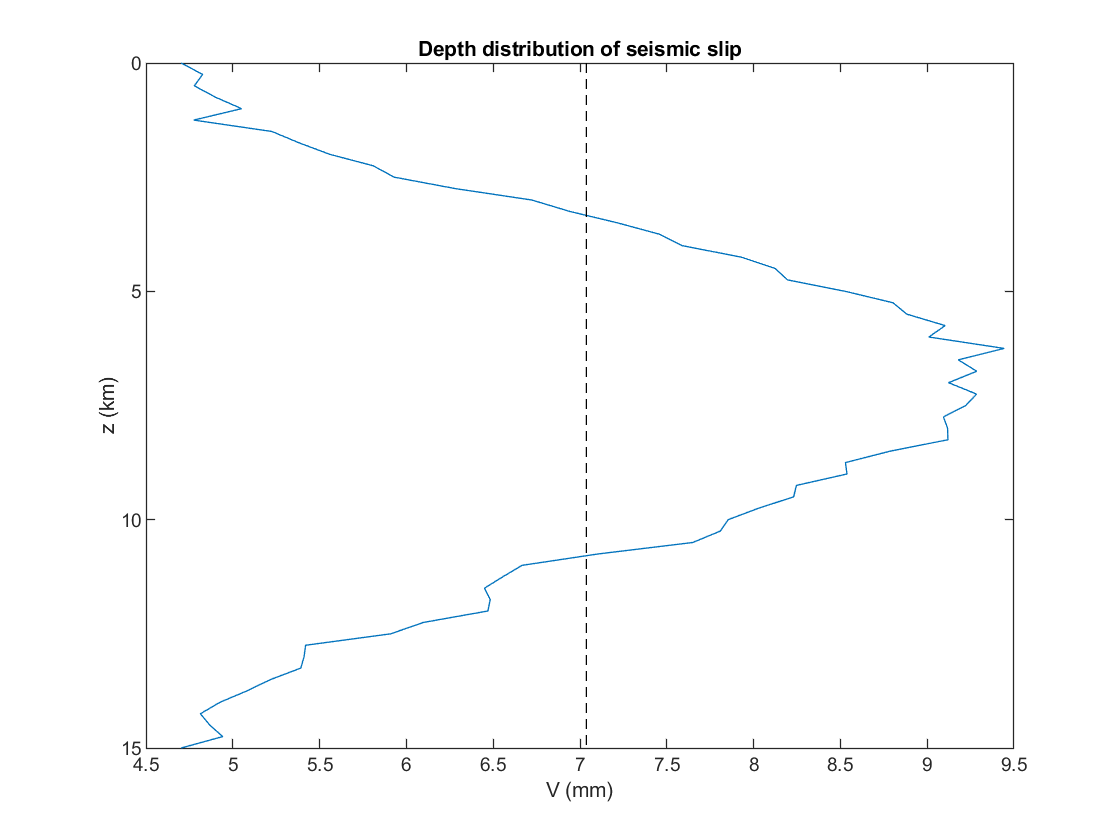


% Velocity depth distribution
figure();
plot((0:parFAULT.res:parFAULT.W).*sind(30)./1000,mean(Slip.D,1)./C);hold on;
plot((0:parFAULT.res:parFAULT.W).*sind(30)./1000,V.*ones(61,1),'k--');hold on;
view(90, 90);xlabel('z (km)');ylabel('V (mm)');
set(gca,'fontsize',7);
title('Depth distribution of seismic slip');

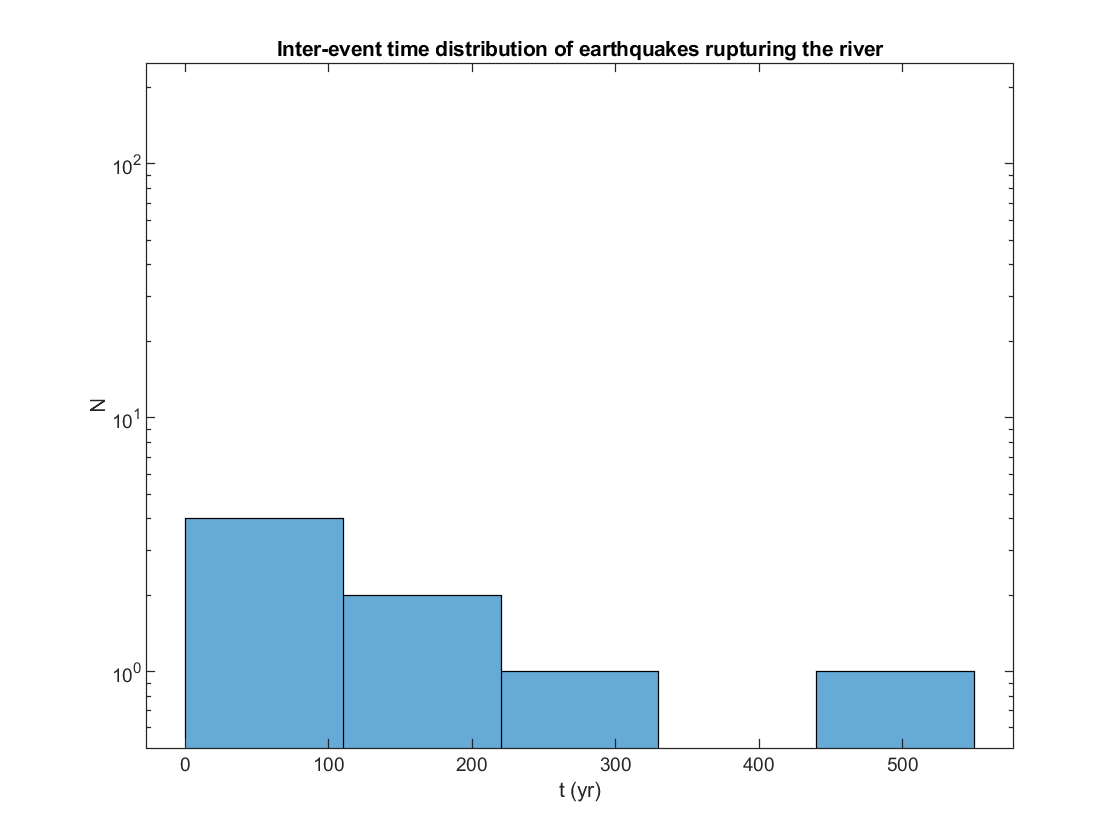


% Inter-event time distribution of river ruptures
figure();
histogram(diff(EQriv.t)./365,5);set(gca,'YScale','log');
xlabel('t (yr)');ylabel('N');ylim([0.5 250]);set(gca,'fontsize',7);
title('Inter-event time distribution of earthquakes rupturing the river');

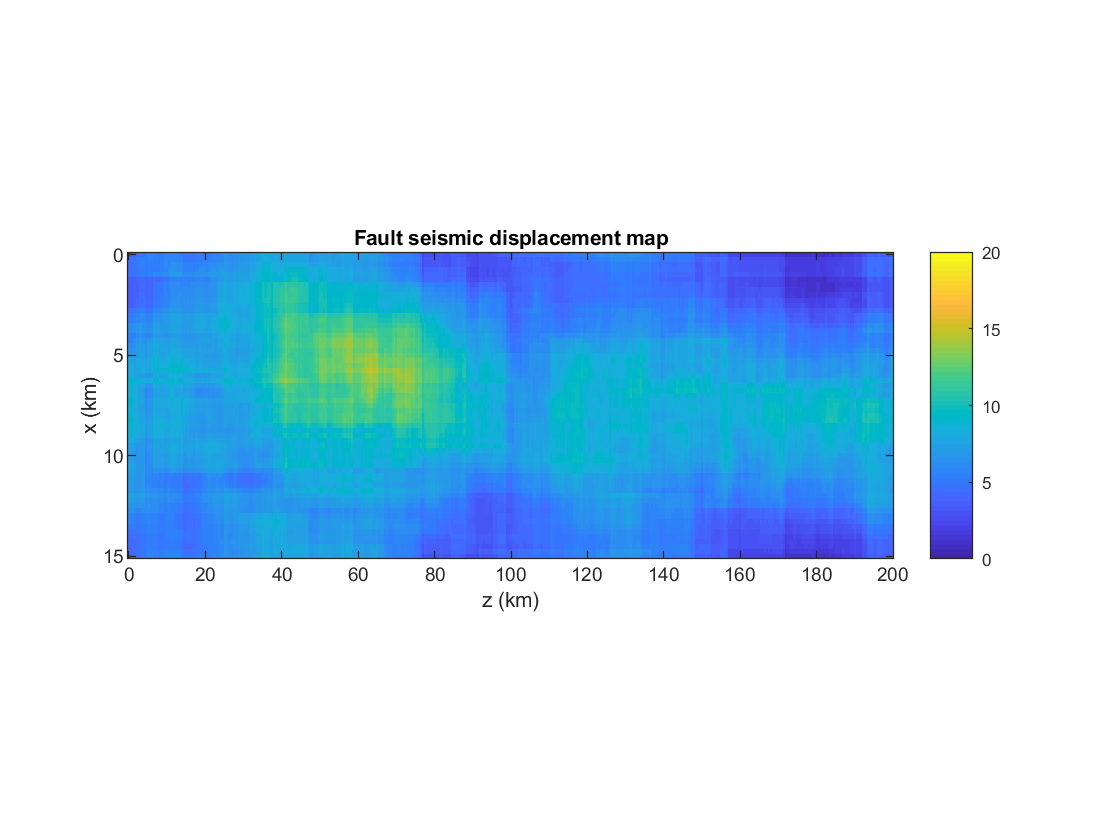


% Co-seismic displacement map
figure();
imagesc(Slip.Y(:,1)./1000,Slip.X(1,:).*sind(30)./1000,Slip.D'./C);axis tight;ylabel('x (km)');xlabel('z (km)');pbaspect([5 2 1])
set(gca,'fontsize',7);caxis([0 20]);colorbar;
title('Fault seismic displacement map');

## River profile

Define a retreat rate for knickpoints

ux=0.1/365; % m/year

Compute river profile

% seismic contribution
dz_seismic=EQriv.D;dx_seismic=dz_seismic.*0;t_seismic=EQriv.t;

% aseismic contribution
uz=(1-parFAULT.chi).*V./365/1000.*parEQ.T./parEQ.T;
dt=diff([0 EQriv.t parEQ.T]);
dz_aseismic=dt.*uz;dx_aseismic=dt.*ux;t_aseismic=dt/2+[0 EQriv.t];

% River profile with co- and a-seismic uplift
dztot=[dz_seismic dz_aseismic];dx=[dx_seismic dx_aseismic];t=[t_seismic t_aseismic];
[t,ind]=sort(t);dztot=dztot(ind);dx=dx(ind);
ztot=0;x=0;
for i=1:numel(t)
    ztot=[ztot ztot(end)+dztot(i)];x=[x x(end)+dx(i)];
end

% River profile with only co-seismic uplift
dzco=[dz_seismic dz_aseismic.*0];dx=[dx_seismic dx_aseismic];t=[t_seismic t_aseismic];
[t,ind]=sort(t);dzco=dzco(ind);dx=dx(ind);
zco=0;x=0;
for i=1:numel(t)
    zco=[zco zco(end)+dzco(i)];x=[x x(end)+dx(i)];
end

## Figure - River profiles

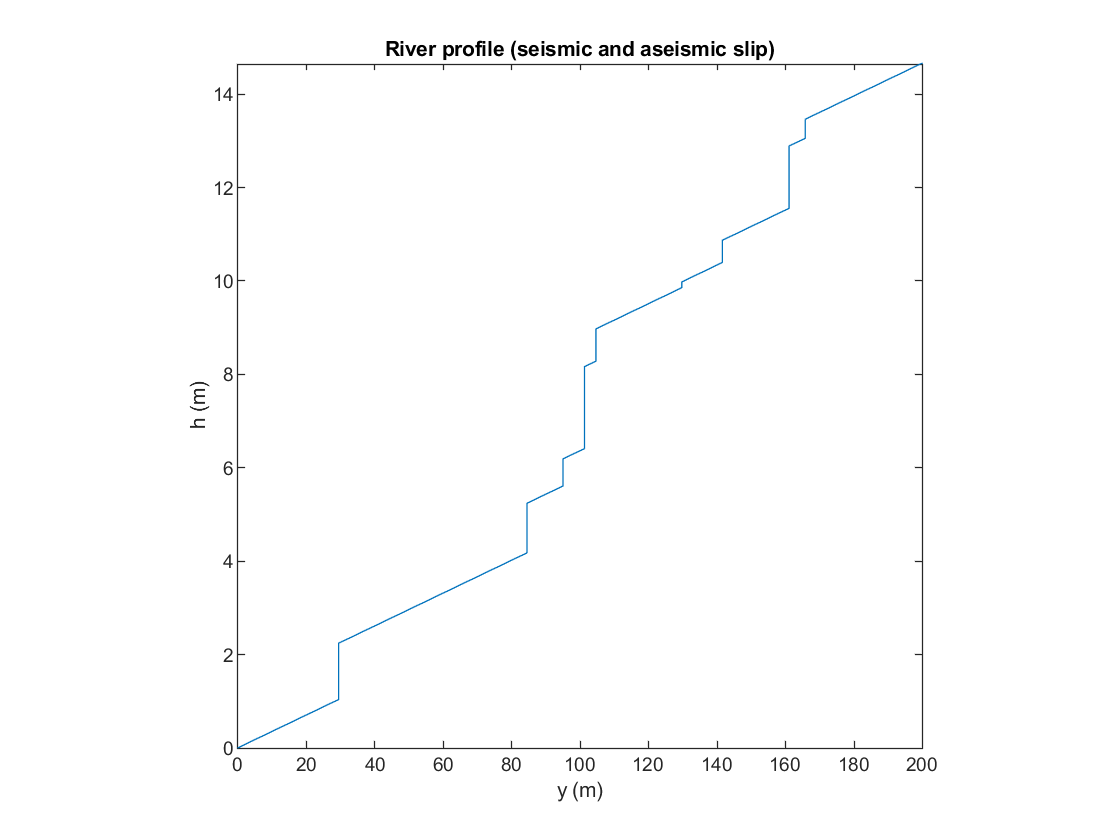

% River profiles - co- and a-seismic displacement
figure();
plot(x,ztot);axis square tight;set(gca,'fontsize',7);xlabel('y (m)');ylabel('h (m)');title('River profile (seismic and aseismic slip)')

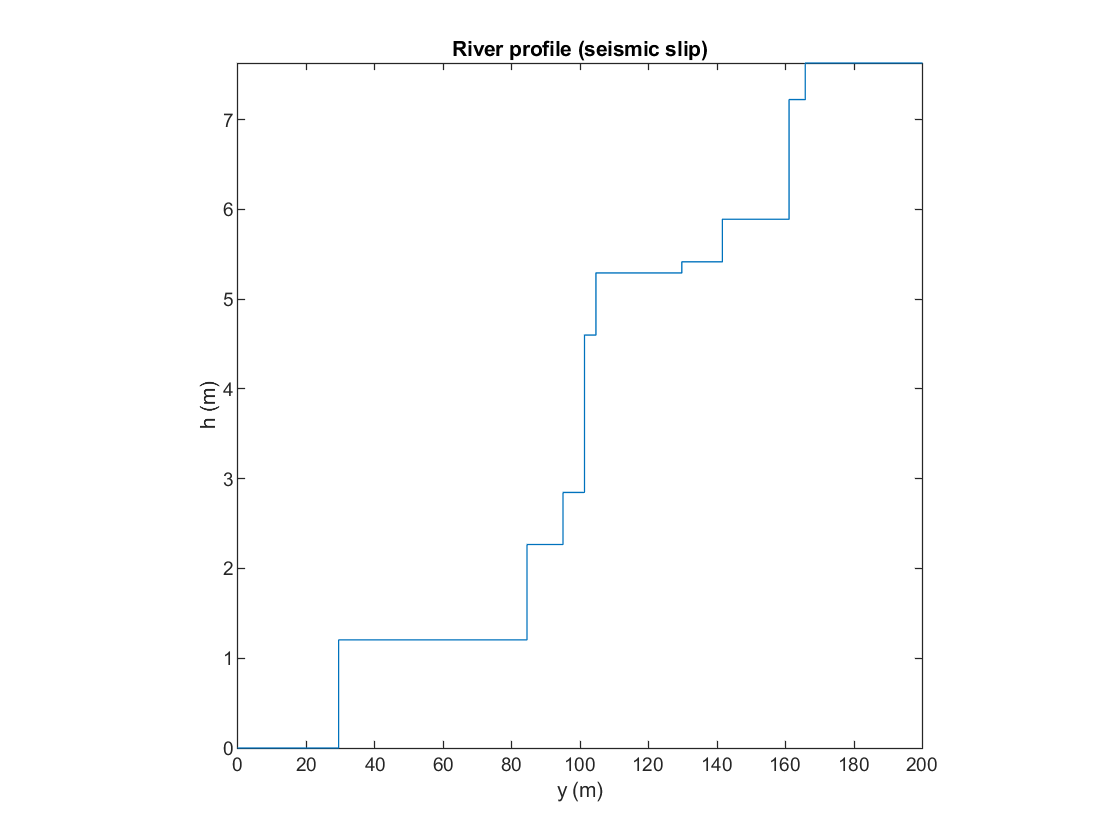


% River profiles - only coseismic uplift
figure();
plot(x,zco);axis square tight;set(gca,'fontsize',7);xlabel('y (m)');ylabel('h (m)');title('River profile (seismic slip)')